demo_costFunctionComponents.m

#### Visualization of the individual components of the cost function

close all;

Xdim = 101; 
Ydim = 101;


% Create a grid to represent the spatial landscape. This landscape is the
% spatial domain of the cost function.
[X,Y] = meshgrid(0:1:Xdim,0:1:Ydim);

### Cost for reaching the goal (no obstacles)

This is the first component of the cost function. It is an attraction term that "attracts" the particle to the goal location. 

% Create a grid with the goal location at every point
g = [ 25, 25 ]';

Gx = X; Gy = Y;

Gx(:,:) = g(1);
Gy(:,:) = g(2);

% Attraction term (i.e., distance to goal). This is the distance to the
% goal (d) (the whole grid at once)
C1 = sqrt( (X - Gx).^2 + (Y - Gy).^2 );        

## Cost for reaching the goal (no obstacles)

This plot shows the cost of reaching the goal from any given location on the plane. 

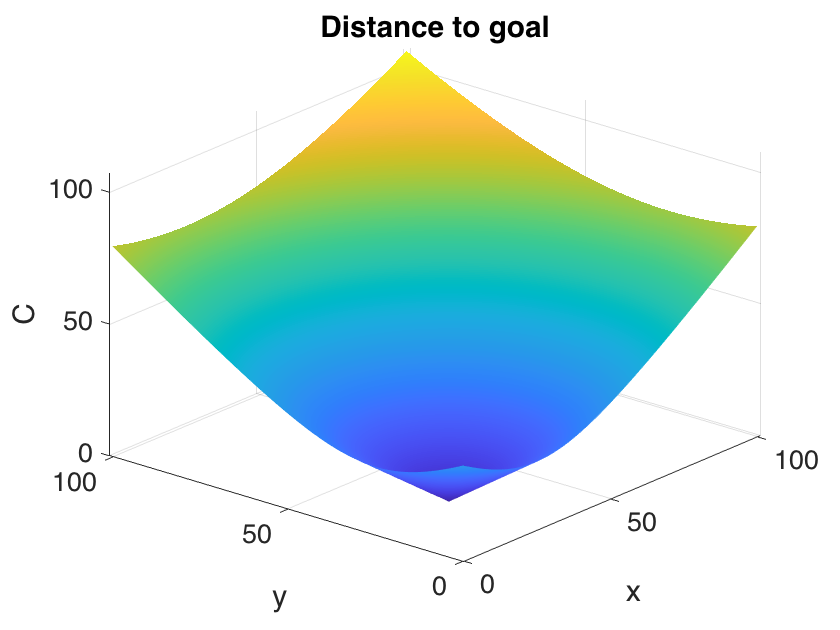

displaySurfPlot(C1, 'Distance to goal', Xdim, Ydim);

## Display gradient of cost function

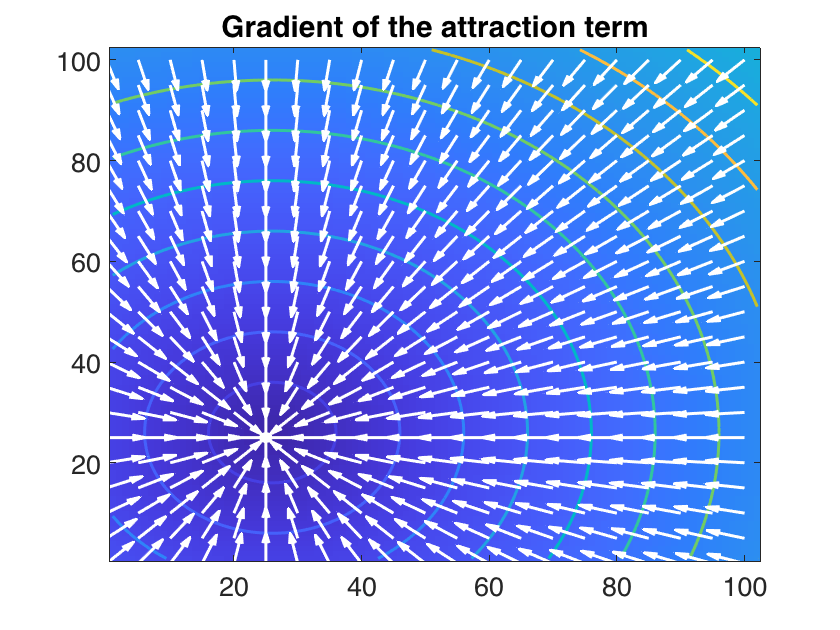

% Calculate the gradient of cost of reaching the goal (no obstacles)
[DX,DY] = gradient(C1); 

% Create a sample grid to display arrows spaced 
delta = 5;
[X1,Y1] = meshgrid(0:delta:Xdim,0:delta:Ydim);

displaySampledGradient(X1, Y1, DX(1:delta:end,1:delta:end), DY(1:delta:end,1:delta:end), C1, 'Gradient of the attraction term','w');

## Cost for obstacle 1 (collision-avoidance term)

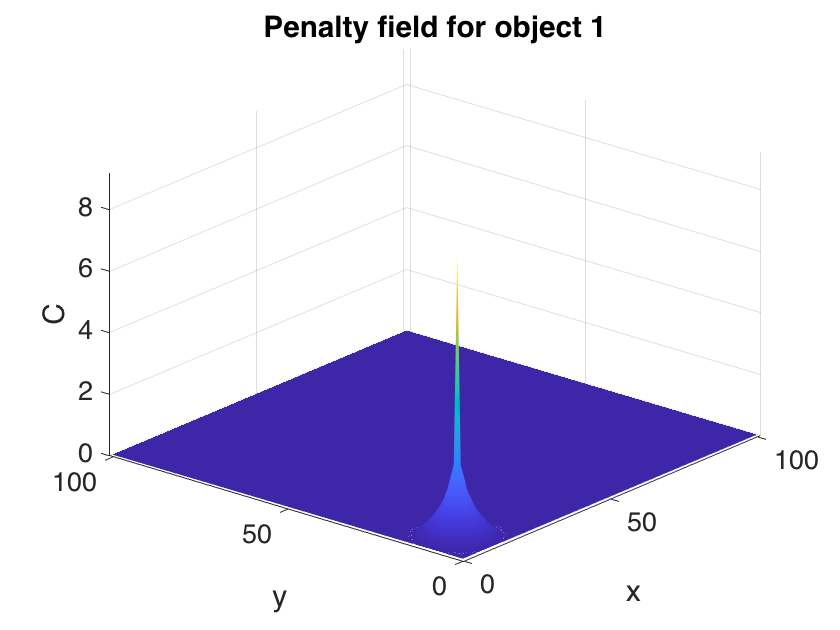

R = 10;                      % Obstacle radius

% Obstacle-avoidance pernaly term (i.e., distance to obstacle)
o = [ 10, 10 ]';

Ox = X; Oy = Y;
Ox(:,:) = o(1);
Oy(:,:) = o(2);

% Distance to the goal (d) (the whole grid at once)
d2 = sqrt( (X - Ox).^2 + (Y - Oy).^2 );   

% Calculate cost term 
C2 = F( d2, R );             % Field function

% Show cost as a surface 
displaySurfPlot(C2, 'Penalty field for object 1', Xdim, Ydim);

## Display gradient of cost function

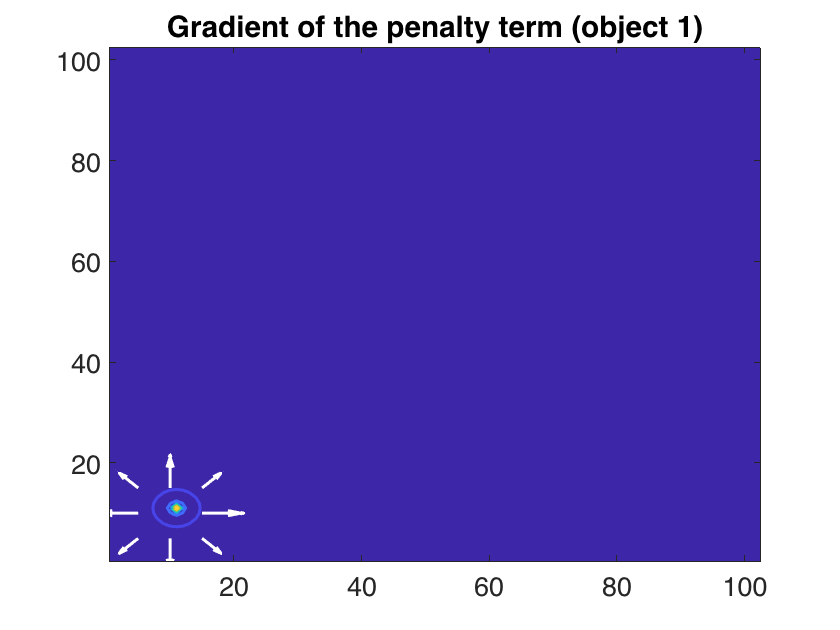

% Calculate the gradient of cost of reaching the goal (no obstacles)
[DX,DY] = gradient(C2); 

% Create a sample grid to display arrows spaced 
delta = 5;
[X1,Y1] = meshgrid(0:delta:Xdim,0:delta:Ydim);

displaySampledGradient(X1, Y1, DX(1:delta:end,1:delta:end), DY(1:delta:end,1:delta:end), C2, 'Gradient of the penalty term (object 1)','w');

## Cost for obstacle 2 (collision-avoidance term)

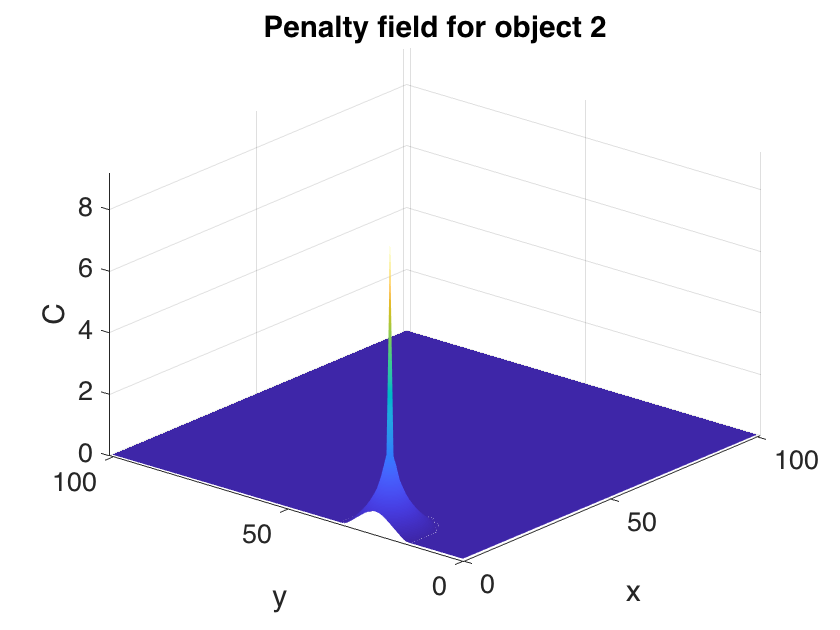

% Obstacle-avoidance pernaly term (i.e., distance to obstacle)
o = [ 5, 25 ]';

Ox = X; Oy = Y;
Ox(:,:) = o(1);
Oy(:,:) = o(2);

% Distance to the goal (d) (the whole grid at once)
d = sqrt( (X - Ox).^2 + (Y - Oy).^2 );   

% Calculate cost term 
C3 = F( d, R );             % Field function

% Show cost as a surface 
displaySurfPlot(C3, 'Penalty field for object 2', Xdim, Ydim);

## Display gradient of cost function 2

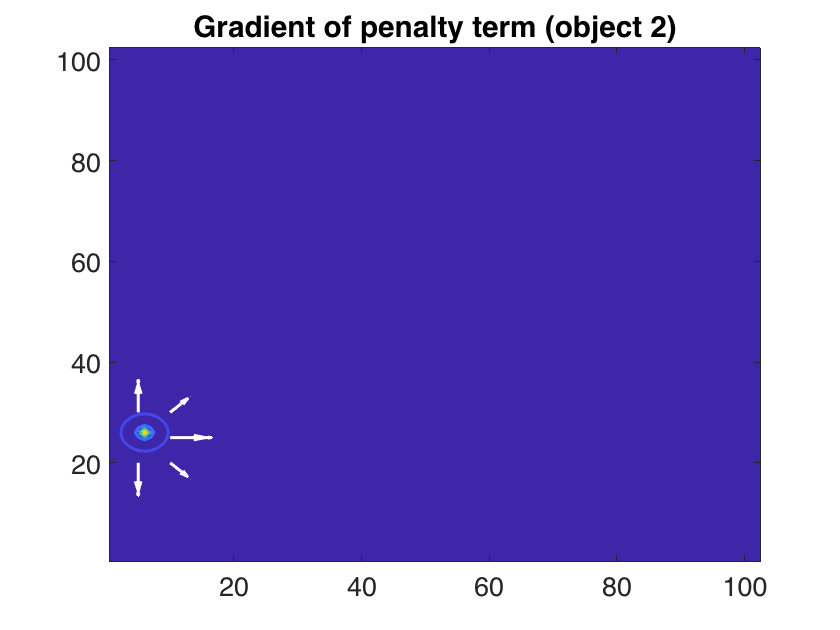

% Calculate the gradient of cost of reaching the goal (no obstacles)
[DX,DY] = gradient(C3); 

% Create a sample grid to display arrows spaced 
delta = 5;
[X1,Y1] = meshgrid(0:delta:Xdim,0:delta:Ydim);

displaySampledGradient(X1, Y1, DX(1:delta:end,1:delta:end), DY(1:delta:end,1:delta:end), C3, 'Gradient of penalty term (object 2)','w');

## Combined penalty terms for all objects

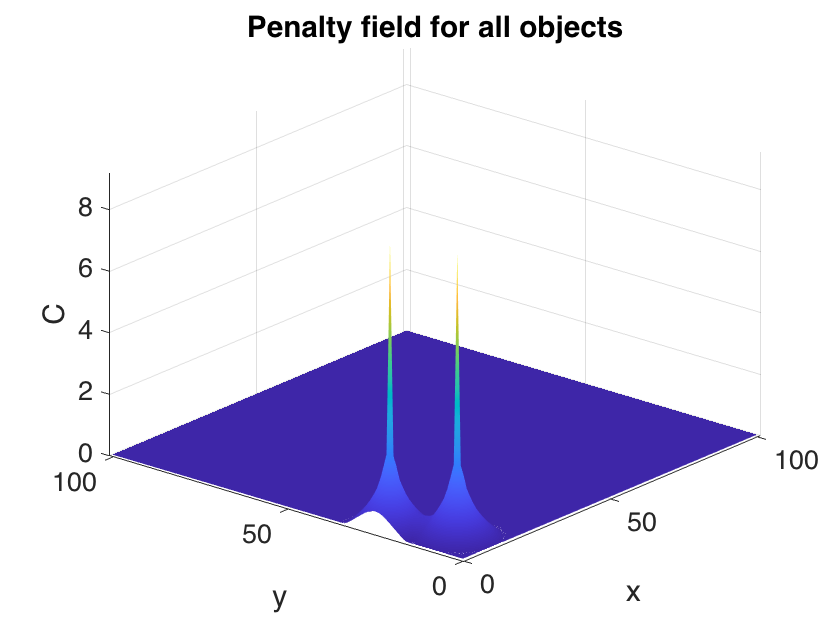

CAllObstacles = (C2 + C3);

% Show cost as a surface 
displaySurfPlot(CAllObstacles, 'Penalty field for all objects', Xdim, Ydim);

## Display gradient of cost function

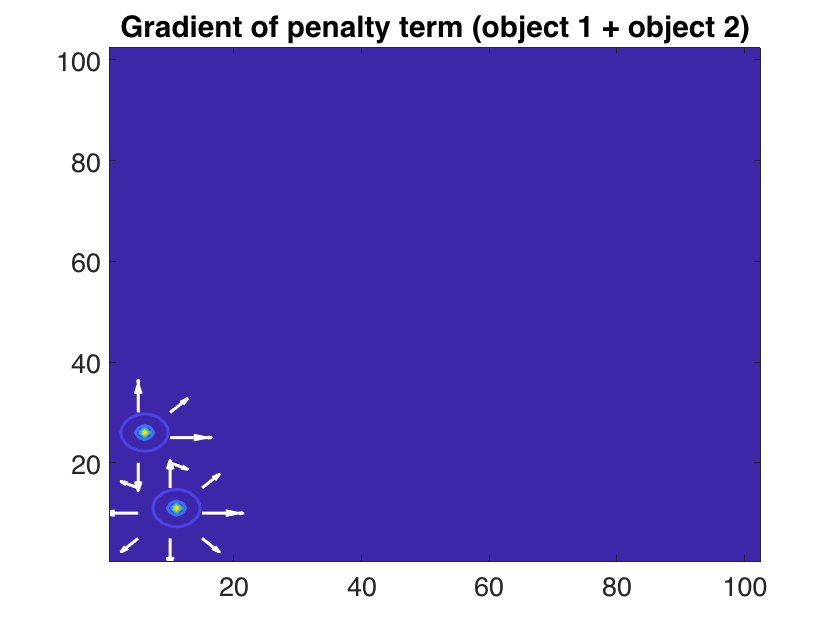

% Calculate the gradient of cost of reaching the goal (no obstacles)
[DX,DY] = gradient(CAllObstacles); 

% Create a sample grid to display arrows spaced 
delta = 5;
[X1,Y1] = meshgrid(0:delta:Xdim,0:delta:Ydim);

displaySampledGradient(X1, Y1, ...
    DX(1:delta:end,1:delta:end), DY(1:delta:end,1:delta:end),...
    CAllObstacles, 'Gradient of penalty term (object 1 + object 2)','w');

## Combined cost terms

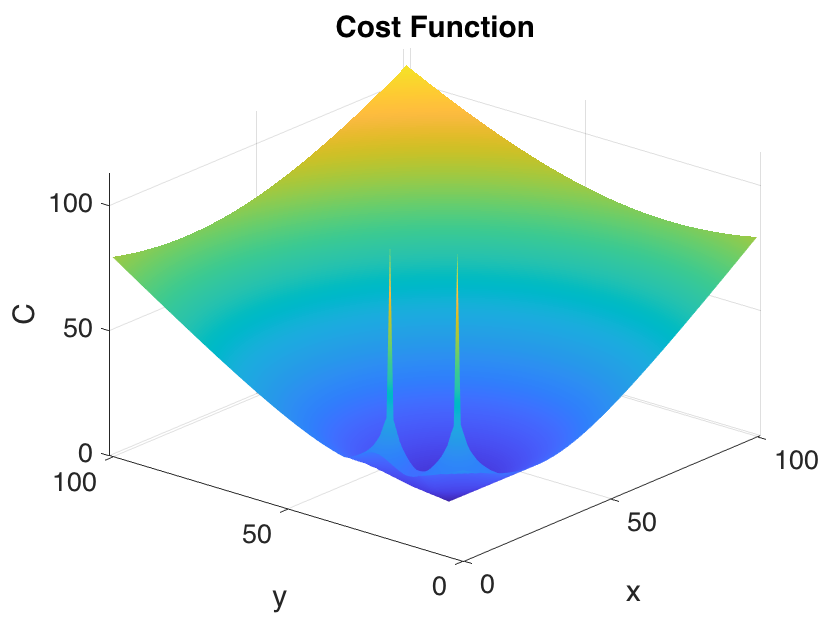

C = C1 + 10*CAllObstacles;   % The whole cost of moving on the landscape to reach the goal location


% Show cost as a surface 
displaySurfPlot(C, 'Cost Function', Xdim, Ydim);

## Display gradient of cost function

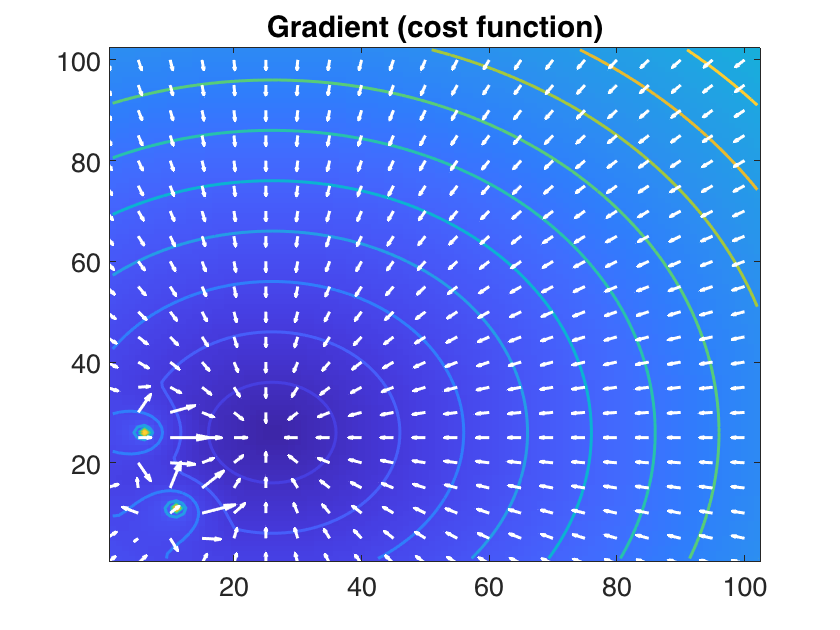

% Calculate the gradient of cost of reaching the goal (no obstacles)
[DX,DY] = gradient(C); 

% Create a sample grid to display arrows spaced 
delta = 5;
[X1,Y1] = meshgrid(0:delta:Xdim,0:delta:Ydim);

displaySampledGradient(X1, Y1, ...
    DX(1:delta:end,1:delta:end), DY(1:delta:end,1:delta:end), ...
    C, 'Gradient (cost function)','w');

function displaySurfPlot(C, plotTitle, Xmax, Ymax)


    figure;
    surf(C,'FaceColor','interp',...
        'EdgeColor','none',...
        'FaceLighting','gouraud')
    axis tight
    view(-50,30)
    xlabel('x','FontSize',18)
    ylabel('y','FontSize',18)
    zlabel('C','FontSize',18)
    set(gca, 'FontSize',18);
    xlim([0 Xmax]);
    ylim([0 Ymax]);
    set(gcf, 'color','w');
    title(plotTitle);

end

function displaySampledGradient(X1, Y1, DX, DY, C, plotTitle, arrowColor)

    figure; set(gcf,'color','w');
    image(C); axis xy;
    hold on;
    contour(C,'linewidth',2)
    hold on
    quiver(X1, Y1, -DX,-DY,'linewidth',2,'color',arrowColor)
    title(plotTitle);
    set(gca, 'FontSize',18);

    hold off

end




% Field (penalty) function for collision-free motion
function f = F(d, R)
    %
    %   d: distance value > 0
    %   R: radius of influence >0
    %

    % If 0 < d <= R then f = ln(R/d)
    idx = d==0;
    d(idx) = .001;
    f = log( R ./ d );

    % If d > R then f(d) = 0
    f(d>R) = 0;

end